# Data Collection for Air Levitation System

Clearing work space and setting up the file path

clear;
clc;
cd 'C:\Users\auw_a\OneDrive - Higher Colleges of Technology\Research\Air Levitating Control System'

## Creating objects for Arduino and Ultrasonic Sensor

Arduino Motor Shield:    Brake pin = 8; Direction pin = 13

Ultrasonic Sensor: Trigger = 4; Echo = 2

% creating Object for the Arudino with required Libraries
a = arduino('COM10','Uno',"Libraries","Ultrasonic") 

a =   arduino with properties:

                  Port: 'COM10'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'Ultrasonic'}
Show all properties



% Creating Ultrasonic Sensor obj with four pins
ultrasonic = ultrasonic(a,'D4','D2')       

ultrasonic =   Ultrasonic with properties:

    TriggerPin: 'D4'
       EchoPin: 'D2'



writeDigitalPin(a,'D8',0);      % Brake Pin
writeDigitalPin(a,'D13',1);     % Direction Pin


Only to run and test the FAN

% PWM = 0;
% DutyCyle = PWM/255;             % converting Decimal PWM to the 0 to 1
% 
% writeDigitalPin(a,'D8',1);      % Brake Pin
% writeDigitalPin(a,'D13',1);     % Direction Pin
% writePWMDutyCycle(a,'D11',DutyCyle); % PWM

## Initializing Variables

k = [8 9 10 12 13 15 17];             % proportional gain
step_time = 0.04;   % sample time

t = 0:step_time:10;        % runtime
distance = zeros(length(t), length(k));
setpoint = 30;

% Controller output saturation limits
upper_limit = 255;
lower_limit = 80;

## Setting up the plot Environment & Collecting Data

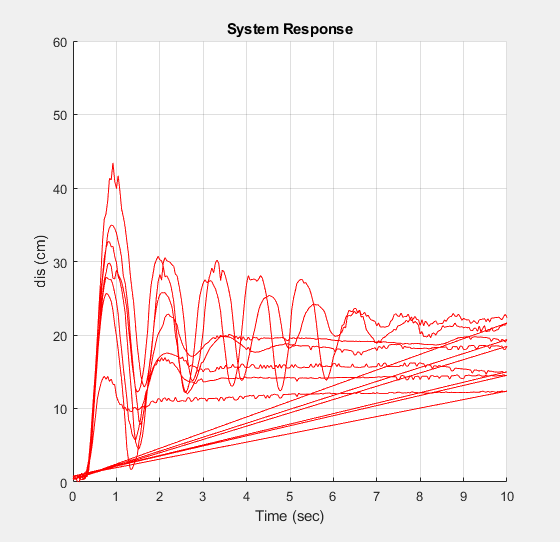

close all;
figure;
set(gcf,'Visible','on')
h = animatedline('Color','r','LineWidth',1);
ylim([0, 60]);
xlabel('Time (sec)');
ylabel('dis (cm)');
grid on;
title('System Response')

for j = 1: length(k)
    for i = 1:length(t)
        distance(i, j) = 52 - (readDistance(ultrasonic) * 100);
        error = (setpoint - distance(i,j));
        plant_IN = error * k(j);
       
        if plant_IN < lower_limit
            plant_IN = lower_limit/255;
        elseif plant_IN > upper_limit
            plant_IN = upper_limit/255;
        else 
            plant_IN = (plant_IN/255);
        end
    
        % disp(['plant_IN: ', num2str(plant_IN), '; Position: ', num2str(distance(i,1)), "Kp = ", num2str(k(j))]);
    
        writePWMDutyCycle(a,'D11',plant_IN);
    
        pause(step_time);
    
        addpoints(h, t(i), distance(i, j));
        drawnow limitrate;
    end
    writePWMDutyCycle(a,'D11', 0);        % stopping the FAN
    error = 0;
    pause(3);
end

## Emergency Stop

writePWMDutyCycle(a,'D11', 0);        % stopping the FAN

## Plotting the result

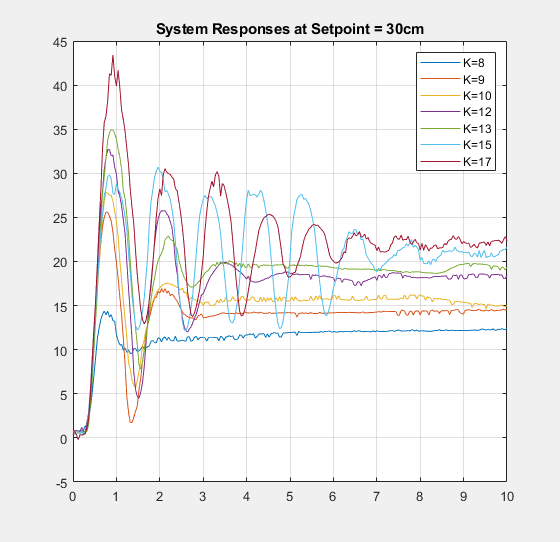

for i = 1: length(k)
    plot(t, distance(:, i))
    hold on;
end
grid on;
legend('K=8', 'K=9', 'K=10', 'K=12', 'K=13', 'K=15', 'K=17');
title("System Responses at Setpoint = 30cm");

## saving varaibales to a MAT file

save ("SysData.mat", "distance", "t", "plant_IN");

## Deleting and clearing the objects

clear a ultrasonic